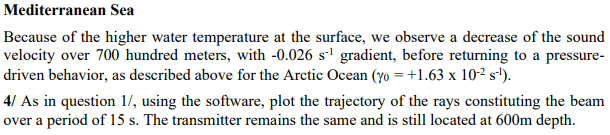

clear
clc
% Initial conditions
Co = 700;
gamma = -0.026;
h = 3500 ; % Depth Seafloor

% Parameter difinition
zs = 600;
total_period = 15; %Total time in seconds
dt = 0.01;
t = 0:dt:total_period;
angle = -2:0.1:2;

n_rows = length(angle);
n_columns = length(t);

ray_matrix = zeros(n_rows, n_columns);


for i = 1:length(angle)
    
    x = zeros(size(t));
    x(1) = 0;
    
    z = zeros(size(t));
    z(1) = zs;
    
    theta = zeros(size(t));
    theta(1)  = angle(i)*pi/180;
    
    c = zeros(size(t));
    c(1)=velocity(z(1),Co,gamma);
    
    ray_matrix(:,1) = z(1);
    
    for j = 2:length(t)
        
        x(j) = x(j-1) + c(j-1) * dt * cos(theta(j-1));
        z(j) = z(j-1) + c(j-1) * dt * sin(theta(j-1));
        c(j) = velocity(z(j),Co,gamma);
        
        % Snail constant
        K = cos(theta(j-1))*c(j)/c(j-1);
        
        if K <= 1
            
            theta(j) = sign(theta(j-1))*acos(K);
            
        else
    
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end
        
    
        if (z(j) <= 0) || (z(j)>=h)
            
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end   
        
%         if x(j) >= 10000
%             angle(i)
%             disp(z(j))
%         end
%         ray_matrix(i,j) =  z(j);
        
    end
    
    hold on
    plot(x,-ray_matrix(i,:))
    
end

title('Ray paths between -2° to 2°.')
xlabel('x') 
ylabel('Depth') 
hold off

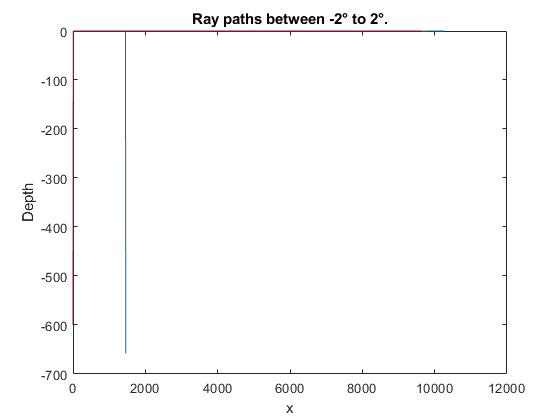

antenna_location = 10000;

[ii,jj] = find(ray_matrix >= antenna_location);
ii

function c = velocity(z, Co, gamma)



ii =

  0×1 empty double column vector



    c = Co + gamma*abs(z);
 
end

function C = velocity_gradient(z, z1, Co, C1, gamma_0, gamma_1 )

    % z1  = Z_inv
    % Co  = surface speed
    % C1  = speed Z_inv
    % z0 =0;     % Z surface
    
    if z<z1
        m = gamma_0;
        C = m*z + c0;
    else
        m = gamma_1;
        b = c1 -m*z1;
        C = m*z + b;
    end
end